## **PROBLEM 1**

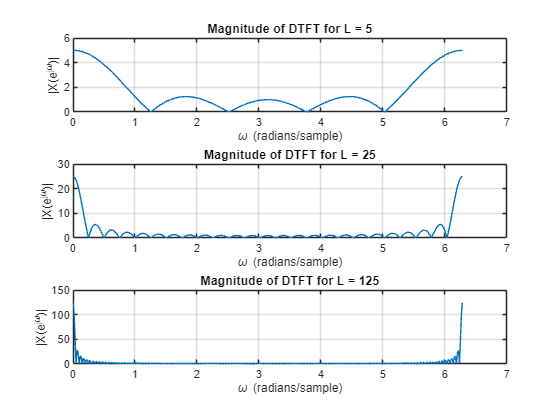

L_values = [5, 25, 125];  
N = 2048;                 
n_total = 256;            

figure
for i = 1:length(L_values)
    L = L_values(i);
    x = [ones(1, L), zeros(1, n_total - L)];
    [H, w] = freqz(x, 1, N, 'whole');
    subplot(3,1,i)
    plot(w, abs(H))
    title(['Magnitude of DTFT for L = ', num2str(L)])
    xlabel('\omega (radians/sample)')
    ylabel('|X(e^{j\omega})|')
    grid on
end

## **PROBLEM 6**

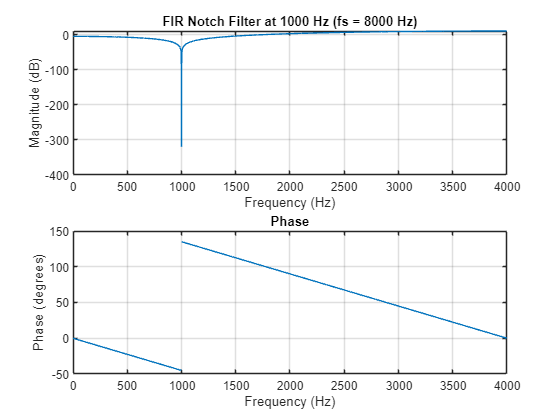

fs1 = 8000;       
f0 = 1000;        
omega0_1 = 2*pi*f0/fs1;    
b1 = [1, -2*cos(omega0_1), 1];
a1 = 1;  

figure;
freqz(b1, a1, 2048, fs1)
title('FIR Notch Filter at 1000 Hz (fs = 8000 Hz)')


disp('Filter coefficients for fs = 8000 Hz:')

Filter coefficients for fs = 8000 Hz:


disp(b1)

    1.0000   -1.4142    1.0000



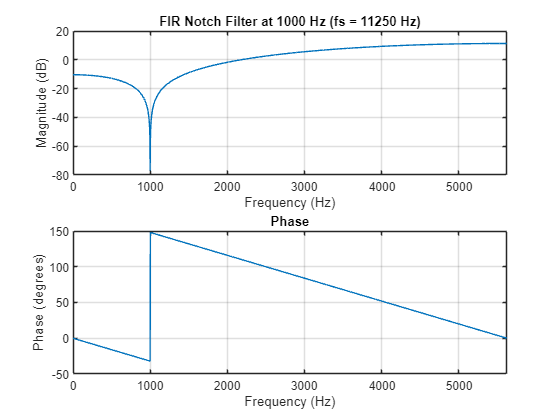


fs2 = 11250;       
omega0_2 = 2*pi*f0/fs2;    

b2 = [1, -2*cos(omega0_2), 1];
a2 = 1;  

figure;
freqz(b2, a2, 2048, fs2)
title('FIR Notch Filter at 1000 Hz (fs = 11250 Hz)')


disp('Filter coefficients for fs = 11250 Hz:')

Filter coefficients for fs = 11250 Hz:


disp(b2)

    1.0000   -1.6961    1.0000



## **PROBLEM 7**

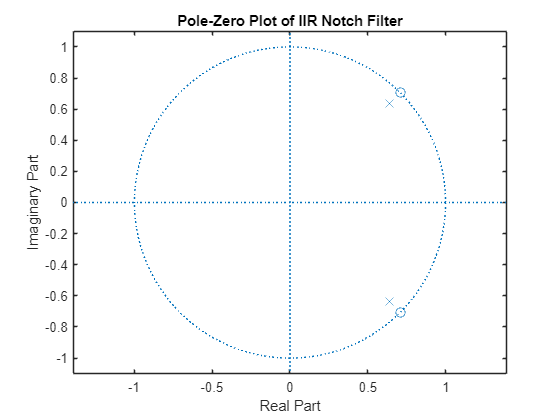

fs = 8000;          
f0 = 1000;          
rho = 0.9;          
omega0 = 2*pi*f0/fs;  
b = [1, -2*cos(omega0), 1];
a = [1, -2*rho*cos(omega0), rho^2];

figure;
zplane(b, a)
title('Pole-Zero Plot of IIR Notch Filter')

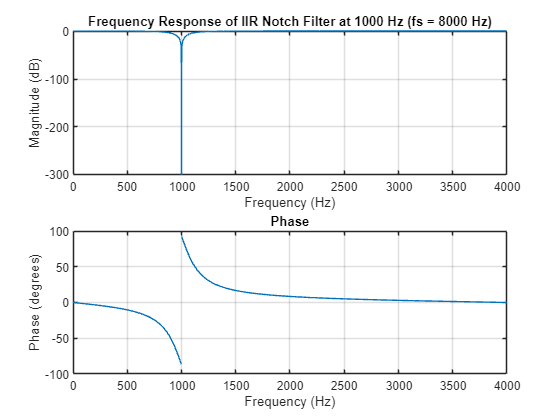


figure;
freqz(b, a, 2048, fs)
title('Frequency Response of IIR Notch Filter at 1000 Hz (fs = 8000 Hz)')


disp('Numerator coefficients b:')

Numerator coefficients b:


disp(b)

    1.0000   -1.4142    1.0000




disp('Denominator coefficients a:')

Denominator coefficients a:


disp(a)

    1.0000   -1.2728    0.8100

